% sample parameters
h=-.1; k=.5; r=1; S_ratio = .85;

% get intersection from |S|/|S0|, h, k, r
% see notebook p61-64 2/1/26

C = quartic_coeffs_2(S_ratio,h,k,r)

C =     1.5476
   -0.2876
   -0.3837
    0.0379
    0.0248


y_sol = roots(C).'

y_sol =     0.4249    0.3880   -0.3494   -0.2777


x_sol = h + [1;-1]*sqrt(r^2 - (y_sol-k).^2);

gamma = x_sol + 1i * y_sol;

resid = S_ratio - sqrt((1-abs(gamma).^2).^2 + (2*imag(gamma)).^2);
idx_keep = abs(resid)<1e-4;
assert(sum(idx_keep(:))==length(y_sol))
x_sol_keep = x_sol(idx_keep)

x_sol_keep =     0.8972
   -1.0937
   -0.6277
    0.5286


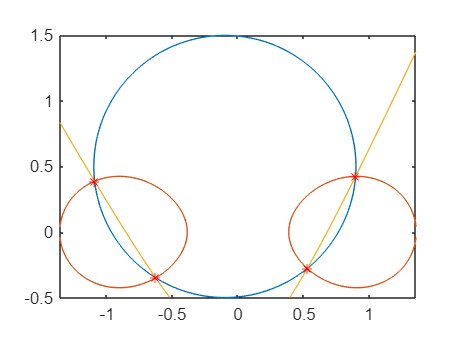


% intersect with hyperbola
%pts = conic_circle_intersect(a,b,c,d,e,f,h,k,r)

% plot
syms x y real
circ = (x-h)^2 + (y-k)^2 - r^2 == 0;
% hyperbola = A*(y+y1)^2 + B*(x+x1)^2 + C*x*y == 1;
S_contor = (1-(x^2+y^2))^2 + 4*y^2 == S_ratio^2;
theta = r^2 - (h^2 + k^2) + 1;
a = h^2-1; %h^2;
b = 2*h*k;
c = k^2;  %k^2 + 1;
d = theta*h;
e = theta*k;
f = theta^2/4 - S_ratio^2/4;
exp = a*x^2 + b*x*y + c*y^2 + d*x + e*y + f;
S_from_coeffs = exp==0;
figure
fimplicit(circ)
hold on
% fimplicit(hyperbola)
fimplicit(S_contor)
axis equal
xx = xlim;
yy = ylim;
fimplicit(S_from_coeffs)
plot(x_sol_keep,y_sol,'r*')
xlim(xx);
ylim(yy);